# **mNevilleTheta**

[Neville theta functions](https://en.wikipedia.org/wiki/Neville_theta_functions)

## Definition


$$\theta_c \left(x|m\right)\equiv \frac{\theta_2 \left(v,q\right)}{\theta_2 \left(0,q\right)}$$



$$\theta_d \left(x|m\right)\equiv \frac{\theta_3 \left(v,q\right)}{\theta_3 \left(0,q\right)}$$



$$\theta_n \left(x|m\right)\equiv \frac{\theta_4 \left(v,q\right)}{\theta_4 \left(0,q\right)}$$



$$\theta_s \left(x|m\right)\equiv \frac{2K\left(m\right)}{\pi }\frac{\theta_1 \left(v,q\right)}{{\theta '}_1 \left(0,q\right)}$$


where m is the parameter, $q=\mathrm{nome}\left(m\right)$ and $v=\frac{\pi x}{2K\left(m\right)}$ [2].

Domain:  $0\le q<1\;$, $-\infty <x<\infty$.   For the specified domain, the  codomain  is the set of real numbers.

Basic features:


$$\theta_c \left(-x|m\right)=\theta_c \left(x|m\right)$$



$$\theta_d \left(-x|m\right)=\theta_d \left(x|m\right)$$



$$\theta_n \left(-x|m\right)=\theta_n \left(x|m\right)$$



$$\theta_s \left(-x|m\right)=-\theta_c \left(x|m\right)$$


Special values:

$\theta_c \left(x\left|0\right.\right)=\mathrm{cos}\left(x\right)$,    $\theta_c \left(x\left|1\right.\right)=1$,       $\theta_c \left(0\left|m\right.\right)=1$

$\theta_d \left(x\left|0\right.\right)=1$,    $\theta_d \left(x\left|1\right.\right)=1$,      $\theta_d \left(0\left|m\right.\right)=1$

$\theta_n \left(x\left|0\right.\right)=1$,    $\theta_n \left(x\left|1\right.\right)=1$,      $\theta_n \left(0\left|m\right.\right)=1$

$\theta_s \left(x|0\right)=\mathrm{sin}\left(x\right)$,    $\theta_s \left(0|m\right)=0$

Identities:


$$\textrm{pq}\left(x|m\right)=\frac{\theta_p \left(x|m\right)}{\theta_q \left(x|m\right)}$$


pq(u,m) is a Jacobi elliptic function (p and q are one of s,c,n,d)

## Syntax

Y = NevilleThetaC( U,Q)

Y = NevilleThetaD( U,Q)

Y = NevilleThetaN( U,Q)

Y = NevilleThetaS( U,Q)

y = nthc( u, q)

y = nthd( u, q)

y = nthn( u, q)

y = nths( u, q)

## Description

**Y = mNevilleThetaX(U,M)** returna the Neville theta function theta {C,D,N,S} for each element of the arrays U and M (parameter). U and M must be real and the same size or any of them can be scalar. NevilleThetaX is the wrapper function which calls the functions **mnthx** element-wise via the function **ufun2**.

**y = mnthx(u,m)** return the value of the Neville theta function theta {c,d,n,s}  for argument u and the nome q. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed. **mnthx** is the wrapper function which calls the functions **nthx **for the actual calculation. 

## **Numerical Examples**

**Scalar input**

Accuracy

format long
m = 0.3;
x = 2.5;
[mnthetac(x,m), mnthetad(x,m), mnthetan(x,m), mnthetas(x,m)]

ans =   -0.659004666767382   0.951821966612676   1.052669335465161   0.820868795245304



[mnthetac(x,m), mNevilleThetaC(x,m)]

ans =   -0.659004666767382  -0.659004666767382


% Maple 0.659004666767381_54967 

[mnthetad(x,m), mNevilleThetaD(x,m)]

ans =    0.951821966612676   0.951821966612676


% Maple  0.951821966612675_61994

[mnthetan(x,m), mNevilleThetaN(x,m)]

ans =    1.052669335465161   1.052669335465161


% Maple 1.052669335465161_3637

[mnthetas(x,m), mNevilleThetaS(x,m)]

ans =    0.820868795245304   0.820868795245304


% Maple 0.820868795245304_00536


Special values

mnthetas(0,0.2)

ans = 0

Identities

m = 0.2;
x = 12;
disp(mjsn(x,m) - mnthetas(x,m)/mnthetan(x,m))

    -4.440892098500626e-16



disp(mjcn(x,m) - mnthetac(x,m)/mnthetan(x,m))

    -1.665334536937735e-15



disp(mjdn(x,m) - mnthetad(x,m)/mnthetan(x,m))

    -4.440892098500626e-16



disp(mjsd(x,m) - mnthetas(x,m)/mnthetad(x,m))

    -8.881784197001252e-16



**Vector input**

x=[1 2 3];
m = 0.5;
disp(mJacobiCN(x,m) - mNevilleThetaC(x,m)./mNevilleThetaN(x,m));

   1.0e-15 *

                   0  -0.194289029309402  -0.111022302462516



**Matrix input**

x=[1 2 3; 4 5 6];
m = 0.5;
disp(mJacobiCN(x,m) - mNevilleThetaC(x,m)./mNevilleThetaN(x,m));

   1.0e-15 *

                   0  -0.194289029309402  -0.111022302462516
   0.111022302462516   0.055511151231258   0.777156117237609



## **Examples**

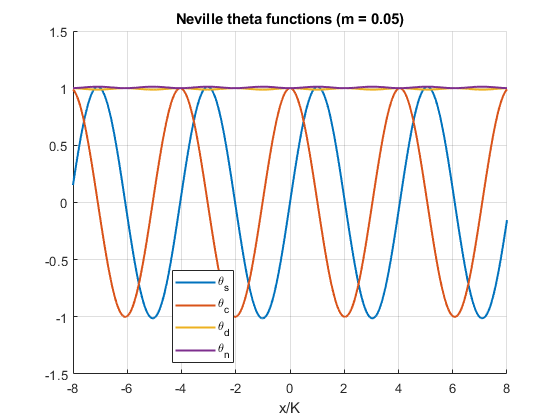

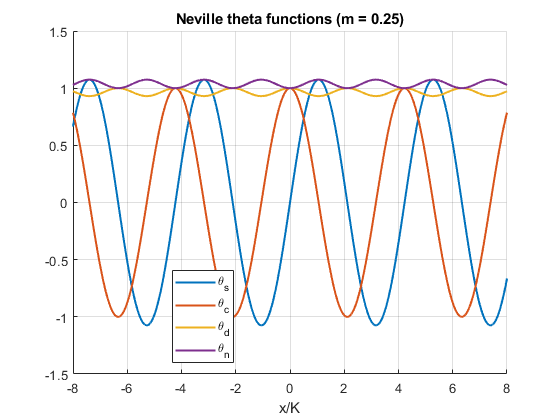

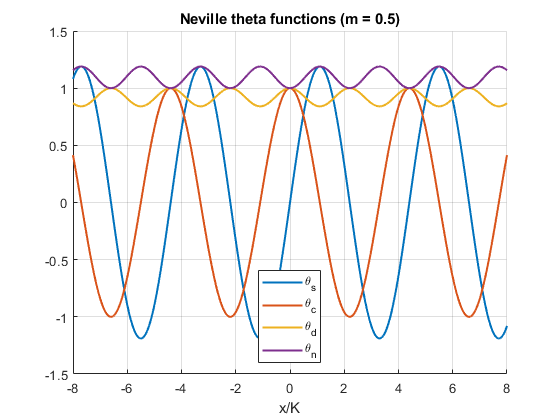

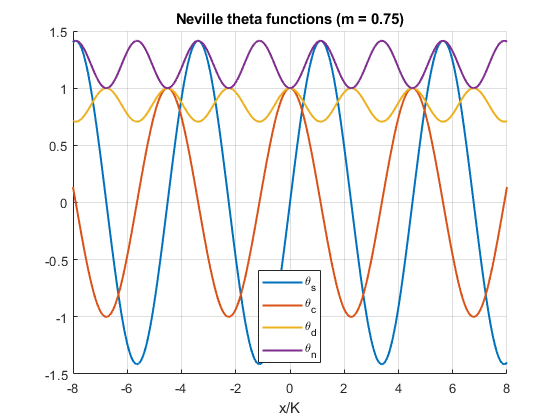

% Fig 20.14 from Beebe - The Mathematical-Function Computation Handbook,
% Springer 2017

x = -8:0.01:8;
mm = [0.05, 0.25, 0.5, 0.75];
for n = 1:4
    m = mm(n);
    figure
    clf
    hold on
    plot(x,mNevilleThetaS(x*elK(m),m),'LineWidth',1.5)
    plot(x,mNevilleThetaC(x*elK(m),m),'LineWidth',1.5)
    plot(x,mNevilleThetaD(x*elK(m),m),'LineWidth',1.5)
    plot(x,mNevilleThetaN(x*elK(m),m),'LineWidth',1.5)
    txt = sprintf('Neville theta functions (m = %g)',m);
    title(txt)
    legend('\theta_{s}','\theta_{c}','\theta_{d}','\theta_{n}',...
        'Location','best') %,'FontSize',14)
    xlabel('x/K')
    grid on
    hold off
end

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Theta Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/20)

[Theta function, Wikipedia](https://en.wikipedia.org/wiki/Theta_function)

## **References**

[1] W.Ehrhardt, "The AMath and DMath Special functions", 2016

[2] N.H.F. Beebe - The Mathematical-Function Computation Handbook, Springer 2017

## See Also